# Hankel Matrix Completion

## Experimenting with LTI's without input

First we get an intuition of state space definition without input. We deal with discrete systems, since we are interested in data sampled at specific time points in history.

% statenum states, outputnum outputs, 0 input
statenum = 100;
outputnum = 1;

state_space = drss(statenum,outputnum,0)

state_space =
 
  A = 
                 x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15         x16         x17         x18         x19         x20         x21         x22         x23         x24         x25         x26         x27         x28         x29         x30         x31         x32         x33         x34         x35         x36         x37         x38         x39         x40         x41         x42         x43         x44         x45         x46         x47         x48         x49         x50         x51         x52         x53         x54         x55         x56         x57         x58         x59         x60         x61         x62         x63         x64         x65         x66         x67         x68         x69         x70         x71         x72         x73         x74         x75         x76         x77         x78         x79         x80         x

dssprop(state_space)

State-space properties: 
    "Number of states: 100"
    "Number of inputs: 0"
    "Number of outputs: 1"

State-space dimensions: 
    "A_rows:100"    "A_cols:100"
    "B_rows:100"    "B_cols:0"  
    "C_rows:1"      "C_cols:100"
    "D_rows:1"      "D_cols:0"  

Max absolute eigen value: 1
Eigen values of A: 
    0.9834
    0.9834
    0.9213
    0.9213
    0.9840
    0.9840
    0.8270
    0.8270
    0.8963
    0.8963
    0.9382
    0.8010
    0.8010
    0.8657
    0.8657
    0.9506
    0.7163
    0.7163
    0.9024
    0.6595
    0.6595
    0.8786
    0.8759
    0.8668
    0.8581
    1.0000
    1.0000
    1.0000
    0.6607
    0.6607
    0.7916
    0.8737
    0.7408
    0.8737
    0.7181
    0.7181
    0.5697
    0.5697
    0.7122
    0.5550
    0.5550
    0.6369
    0.5004
    0.5004
    0.5880
    0.5820
    0.5852
    0.5655
    0.5728
    0.3911
    0.3911
    0.4933
    0.4217
    0.4684
    0.3596
    0.3596
    0.4060
    0.4060
    0.3294
    0.3294
    0.4001
    0.2465
    0

Now we create a set of outputs, with x(0) = x_0 != 0 (since we dont have an input and thus if the state is the zero vector the transfer function will not do anything to the state)

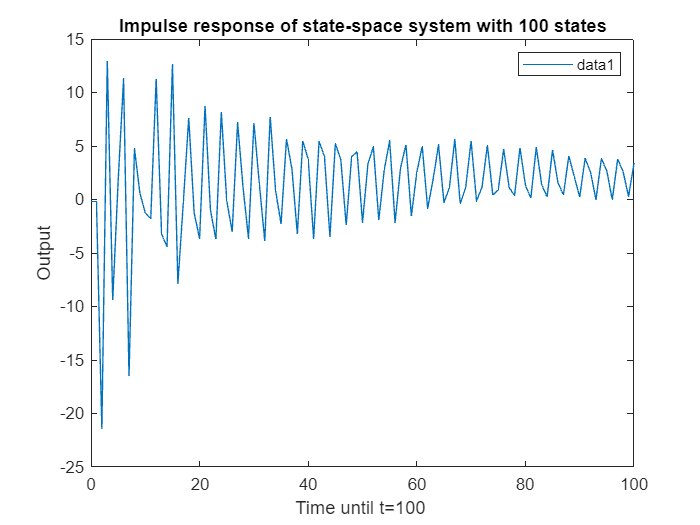

maxTime = 100;

figure;
dssplot(state_space,maxTime);

Notice that its possible for one of the eigenvalues to be exactly 1, which is neither stable nor unstable (marginally stable). Using the drss function we can generate many different kinds of discrete-time state-space systems that are stable. In the plot we observe that after a large enough T the impulse response stabilizes.

## Experimenting with LTI's with input

We can also generate an LTI with an input vector upon which a transformation B and D have an effect on the state change and output. We can have a single-input or multi-input.

% statenum states, outputnum outputs, inputnum input
statenum = 100;
outputnum = 4;
inputnum = 4;
maxTime = 100;
input = [2;1;2;3];


state_space = drss(statenum,outputnum,inputnum)

state_space =
 
  A = 
                 x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15         x16         x17         x18         x19         x20         x21         x22         x23         x24         x25         x26         x27         x28         x29         x30         x31         x32         x33         x34         x35         x36         x37         x38         x39         x40         x41         x42         x43         x44         x45         x46         x47         x48         x49         x50         x51         x52         x53         x54         x55         x56         x57         x58         x59         x60         x61         x62         x63         x64         x65         x66         x67         x68         x69         x70         x71         x72         x73         x74         x75         x76         x77         x78         x79         x80         x

dssprop(state_space)

State-space properties: 
    "Number of states: 100"
    "Number of inputs: 4"
    "Number of outputs: 4"

State-space dimensions: 
    "A_rows:100"    "A_cols:100"
    "B_rows:100"    "B_cols:4"  
    "C_rows:4"      "C_cols:100"
    "D_rows:4"      "D_cols:4"  

Max absolute eigen value: 1
Eigen values of A: 
    0.9429
    0.9429
    0.9051
    0.9051
    0.9188
    0.9188
    0.9807
    0.9785
    0.9340
    0.9072
    0.9032
    0.9700
    0.9645
    0.9580
    1.0000
    1.0000
    0.8864
    0.9179
    0.6828
    0.6828
    0.8741
    0.8662
    0.6580
    0.6580
    0.7939
    0.6202
    0.6202
    0.7405
    0.8538
    0.7001
    0.8538
    0.5757
    0.5757
    0.7739
    0.7739
    0.7164
    0.7053
    0.6286
    0.6703
    0.5805
    0.6486
    0.4586
    0.4586
    0.5091
    0.5029
    0.4857
    0.4158
    0.4158
    0.4357
    0.4357
    0.5710
    0.5654
    0.5610
    0.4220
    0.4220
    0.5115
    0.4930
    0.3676
    0.3676
    0.3992
    0.3992
    0.3469
    0

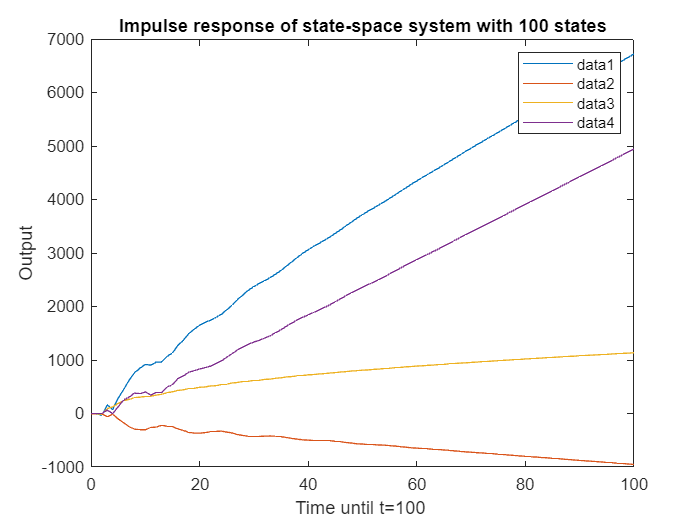

figure;
dssplot(state_space,maxTime,input);

Lets plot the trajectory of the impulse response with the old input and some new input.

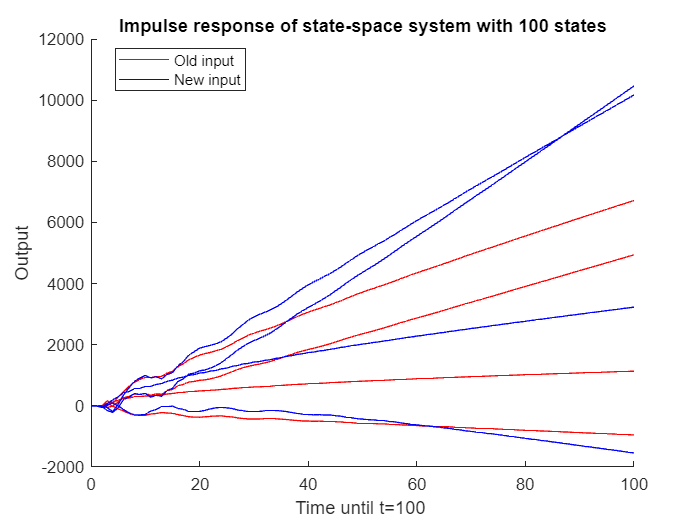

figure;
hold on
f1 = dssplot(state_space,maxTime,input);
f2 = dssplot(state_space,maxTime,[2;1;5;6]);
set(f1, 'Color', 'r');
set(f2, 'Color', 'b');
legend([f1(1), f2(1)], {'Old input', 'New input'}, 'Location', 'best');
hold off;

## Experimenting with Hankel Matrices

Now we're going to experiment with hankel matrices and show how it is relevant to time-series data.  Firstly, we create a drss and with a single in- and output and random initial conditions. We then convert the output to a hankel matrix.

input = 2;
inputnum = 1;
outputnum = 1; 
statenum = 3;
maxTime = 50;

dss = drss(statenum, outputnum, inputnum)

dss =
 
  A = 
          x1     x2     x3
   x1  0.588  5.046  4.075
   x2  2.391   8.99  7.785
   x3  -2.18  -12.9  -10.7
 
  B = 
            u1
   x1    2.225
   x2        0
   x3  -0.4962
 
  C = 
           x1      x2      x3
   y1  -0.638  0.2281  0.7582
 
  D = 
            u1
   y1  -0.2035
 
Sample time: unspecified
Discrete-time state-space model.


[x,y] = dsssim(dss,maxTime,input)

x =     0.7402   10.6290    1.9008   21.6879    1.1762   22.1777    2.0713   21.0625    3.3441   19.7998    4.5608   18.6542    5.6300   17.6616    6.5491   16.8117    7.3346   16.0861    8.0047   15.4672    8.5763   14.9394    9.0636   14.4894    9.4792   14.1056    9.8335   13.7784   10.1357   13.4994   10.3933   13.2615   10.6130   13.0587   10.8003   12.8857   10.9600   12.7382   11.0962   12.6124   11.2124   12.5052   11.3114   12.4138   11.3958   12.3358   11.4678   12.2693   11.5292   12.2126
    0.5629   12.3769    0.5397   34.9919   -1.5548   36.3732   -0.1231   34.4446    2.1510   32.1642    4.3603   30.0789    6.3091   28.2686    7.9861   26.7175    9.4196   25.3932   10.6428   24.2636   11.6860   23.3002   12.5755   22.4788   13.3340   21.7784   13.9808   21.1812   14.5323   20.6719   15.0025   20.2377   15.4035   19.8675   15.7454   19.5517   16.0369   19.2825   16.2855   19.0530   16.4975   18.8573   16.6782   18.6904   16.8323   18.5481   16.9637   18.4267   17.0758   18

y =     0.1964   -0.2106  -17.6236    0.9963  -42.0999    3.1180  -43.2814    1.2237  -40.8401   -1.5791  -38.0489   -4.2721  -35.5113   -6.6413  -33.3116   -8.6785  -31.4276  -10.4196  -29.8191  -11.9051  -28.4472  -13.1720  -27.2773  -14.2524  -26.2797  -15.1735  -25.4291  -15.9590  -24.7038  -16.6288  -24.0853  -17.1999  -23.5579  -17.6869  -23.1083  -18.1021  -22.7248  -18.4562  -22.3979  -18.7581  -22.1191  -19.0155  -21.8814  -19.2350  -21.6787  -19.4222  -21.5059  -19.5818  -21.3585  -19.7178


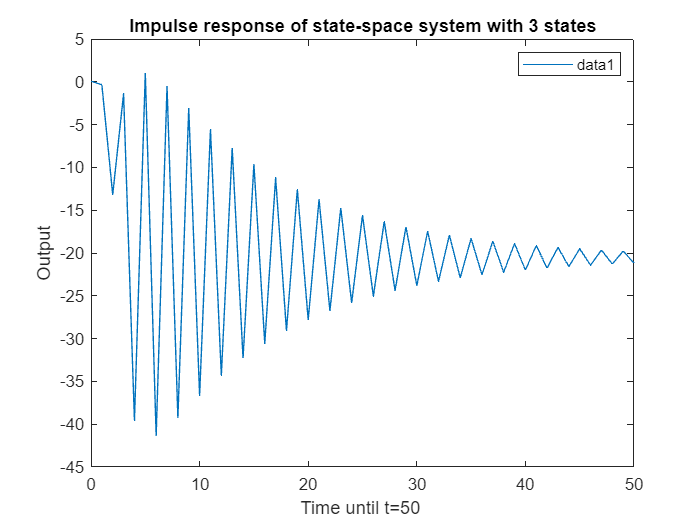

dssplot(dss,maxTime,input);

delta = 26

delta = 26

c = y(1,1:delta)

c =     0.1964   -0.2106  -17.6236    0.9963  -42.0999    3.1180  -43.2814    1.2237  -40.8401   -1.5791  -38.0489   -4.2721  -35.5113   -6.6413  -33.3116   -8.6785  -31.4276  -10.4196  -29.8191  -11.9051  -28.4472  -13.1720  -27.2773  -14.2524  -26.2797  -15.1735


r =y(1,delta:size(y,2))

r =   -15.1735  -25.4291  -15.9590  -24.7038  -16.6288  -24.0853  -17.1999  -23.5579  -17.6869  -23.1083  -18.1021  -22.7248  -18.4562  -22.3979  -18.7581  -22.1191  -19.0155  -21.8814  -19.2350  -21.6787  -19.4222  -21.5059  -19.5818  -21.3585  -19.7178  -21.2328


H = hankel(c,r)

H =     0.1964   -0.2106  -17.6236    0.9963  -42.0999    3.1180  -43.2814    1.2237  -40.8401   -1.5791  -38.0489   -4.2721  -35.5113   -6.6413  -33.3116   -8.6785  -31.4276  -10.4196  -29.8191  -11.9051  -28.4472  -13.1720  -27.2773  -14.2524  -26.2797  -15.1735
   -0.2106  -17.6236    0.9963  -42.0999    3.1180  -43.2814    1.2237  -40.8401   -1.5791  -38.0489   -4.2721  -35.5113   -6.6413  -33.3116   -8.6785  -31.4276  -10.4196  -29.8191  -11.9051  -28.4472  -13.1720  -27.2773  -14.2524  -26.2797  -15.1735  -25.4291
  -17.6236    0.9963  -42.0999    3.1180  -43.2814    1.2237  -40.8401   -1.5791  -38.0489   -4.2721  -35.5113   -6.6413  -33.3116   -8.6785  -31.4276  -10.4196  -29.8191  -11.9051  -28.4472  -13.1720  -27.2773  -14.2524  -26.2797  -15.1735  -25.4291  -15.9590
    0.9963  -42.0999    3.1180  -43.2814    1.2237  -40.8401   -1.5791  -38.0489   -4.2721  -35.5113   -6.6413  -33.3116   -8.6785  -31.4276  -10.4196  -29.8191  -11.9051  -28.4472  -13.1720  -27.2773  -14.2524  -

We can also use our hankelizeM function for quick hankel matrix generation with a specific lag length.

H = hankelizeM(y,26)

H =     0.1964   -0.2106  -17.6236    0.9963  -42.0999    3.1180  -43.2814    1.2237  -40.8401   -1.5791  -38.0489   -4.2721  -35.5113   -6.6413  -33.3116   -8.6785  -31.4276  -10.4196  -29.8191  -11.9051  -28.4472  -13.1720  -27.2773  -14.2524  -26.2797  -15.1735
   -0.2106  -17.6236    0.9963  -42.0999    3.1180  -43.2814    1.2237  -40.8401   -1.5791  -38.0489   -4.2721  -35.5113   -6.6413  -33.3116   -8.6785  -31.4276  -10.4196  -29.8191  -11.9051  -28.4472  -13.1720  -27.2773  -14.2524  -26.2797  -15.1735  -25.4291
  -17.6236    0.9963  -42.0999    3.1180  -43.2814    1.2237  -40.8401   -1.5791  -38.0489   -4.2721  -35.5113   -6.6413  -33.3116   -8.6785  -31.4276  -10.4196  -29.8191  -11.9051  -28.4472  -13.1720  -27.2773  -14.2524  -26.2797  -15.1735  -25.4291  -15.9590
    0.9963  -42.0999    3.1180  -43.2814    1.2237  -40.8401   -1.5791  -38.0489   -4.2721  -35.5113   -6.6413  -33.3116   -8.6785  -31.4276  -10.4196  -29.8191  -11.9051  -28.4472  -13.1720  -27.2773  -14.2524  -

We can change the lag length to create different dimensions of our hankel matrix

hankelizeM(y,10)

ans =     0.1964   -0.2106  -17.6236    0.9963  -42.0999    3.1180  -43.2814    1.2237  -40.8401   -1.5791  -38.0489   -4.2721  -35.5113   -6.6413  -33.3116   -8.6785  -31.4276  -10.4196  -29.8191  -11.9051  -28.4472  -13.1720  -27.2773  -14.2524  -26.2797  -15.1735  -25.4291  -15.9590  -24.7038  -16.6288  -24.0853  -17.1999  -23.5579  -17.6869  -23.1083  -18.1021  -22.7248  -18.4562  -22.3979  -18.7581  -22.1191  -19.0155
   -0.2106  -17.6236    0.9963  -42.0999    3.1180  -43.2814    1.2237  -40.8401   -1.5791  -38.0489   -4.2721  -35.5113   -6.6413  -33.3116   -8.6785  -31.4276  -10.4196  -29.8191  -11.9051  -28.4472  -13.1720  -27.2773  -14.2524  -26.2797  -15.1735  -25.4291  -15.9590  -24.7038  -16.6288  -24.0853  -17.1999  -23.5579  -17.6869  -23.1083  -18.1021  -22.7248  -18.4562  -22.3979  -18.7581  -22.1191  -19.0155  -21.8814
  -17.6236    0.9963  -42.0999    3.1180  -43.2814    1.2237  -40.8401   -1.5791  -38.0489   -4.2721  -35.5113   -6.6413  -33.3116   -8.6785  -31.4276  

hankelizeM(y,30)

ans =     0.1964   -0.2106  -17.6236    0.9963  -42.0999    3.1180  -43.2814    1.2237  -40.8401   -1.5791  -38.0489   -4.2721  -35.5113   -6.6413  -33.3116   -8.6785  -31.4276  -10.4196  -29.8191  -11.9051  -28.4472  -13.1720
   -0.2106  -17.6236    0.9963  -42.0999    3.1180  -43.2814    1.2237  -40.8401   -1.5791  -38.0489   -4.2721  -35.5113   -6.6413  -33.3116   -8.6785  -31.4276  -10.4196  -29.8191  -11.9051  -28.4472  -13.1720  -27.2773
  -17.6236    0.9963  -42.0999    3.1180  -43.2814    1.2237  -40.8401   -1.5791  -38.0489   -4.2721  -35.5113   -6.6413  -33.3116   -8.6785  -31.4276  -10.4196  -29.8191  -11.9051  -28.4472  -13.1720  -27.2773  -14.2524
    0.9963  -42.0999    3.1180  -43.2814    1.2237  -40.8401   -1.5791  -38.0489   -4.2721  -35.5113   -6.6413  -33.3116   -8.6785  -31.4276  -10.4196  -29.8191  -11.9051  -28.4472  -13.1720  -27.2773  -14.2524  -26.2797
  -42.0999    3.1180  -43.2814    1.2237  -40.8401   -1.5791  -38.0489   -4.2721  -35.5113   -6.6413  -33.3116

We can view every row of the Hankel matrices as a sliding window over some data, which is why this offers insight into the inherent patterns and dynamics of the data/system. Once converted the data into this Hankel structure, it is possible to apply different decomposition techniques which we can then use e.g. in signal analysis to separate the main trend from noise. This structure and its sliding window over every row also offers contextual  features, which are important for forcasting and thus also relevant to our research.

## Experimenting with Hankel Matrix and making predictions

From here we can experiment with many different ways of predicting future outputs/points. 

### Hankel nuclear norm heuristic completion

We are now using the nuclear norm heuristic for completing the matrix as described in Dreesen, P., & Markovsky, I. (2019). Data-driven Simulation Using the Nuclear Norm Heuristic. *ICASSP, IEEE International Conference on Acoustics, Speech and Signal Processing - Proceedings*, *2019-May*. [https://doi.org/10.1109/ICASSP.2019.8682993.](https://doi.org/10.1109/ICASSP.2019.8682993.) We'll focus specifically on making future predictions

% Example time series data
data = sin(4 * (1:20))' + 0.02*randn(20, 1);
dataLength = length(data);
L = 10;  % Number of lags (rows in the Hankel matrix)
N = dataLength - L + 1;  % Total columns in the Hankel matrix

% Create the full Hankel matrix without missing values initially
HankelMatrix = hankel(data(1:L), data(L:end));

% Define the number of points we want to predict (missing at the end)
numPredict = 1;

% Create a logical mask for the Hankel matrix with all ones (no missing data)
mask = true(size(HankelMatrix));

% Identify the columns in the Hankel matrix that correspond to the last 'numPredict' points
% These points appea5r in the last 'numPredict' rows of the last columns
for i = 1:numPredict
    mask(end-i+1, end-numPredict+i:end) = false;
end

% Now, apply the mask to set the last 'numPredict' points as NaN (missing)
HankelMatrix(~mask) = NaN;

% Display the mask and modified Hankel matrix to check
disp(mask);

   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   0



disp(HankelMatrix);

   -0.7578    0.9834   -0.5229   -0.2906    0.9157   -0.9123    0.2692    0.5461   -1.0187    0.7299   -0.0055
    0.9834   -0.5229   -0.2906    0.9157   -0.9123    0.2692    0.5461   -1.0187    0.7299   -0.0055   -0.7702
   -0.5229   -0.2906    0.9157   -0.9123    0.2692    0.5461   -1.0187    0.7299   -0.0055   -0.7702    0.9896
   -0.2906    0.9157   -0.9123    0.2692    0.5461   -1.0187    0.7299   -0.0055   -0.7702    0.9896   -0.5184
    0.9157   -0.9123    0.2692    0.5461   -1.0187    0.7299   -0.0055   -0.7702    0.9896   -0.5184   -0.3329
   -0.9123    0.2692    0.5461   -1.0187    0.7299   -0.0055   -0.7702    0.9896   -0.5184   -0.3329    0.9488
    0.2692    0.5461   -1.0187    0.7299   -0.0055   -0.7702    0.9896   -0.5184   -0.3329    0.9488   -0.8820
    0.5461   -1.0187    0.7299   -0.0055   -0.7702    0.9896   -0.5184   -0.3329    0.9488   -0.8820    0.2572
   -1.0187    0.7299   -0.0055   -0.7702    0.9896   -0.5184   -0.3329    0.9488   -0.8820    0.2572    0.5939
 

% Proceed with matrix completion using the nuclear norm minimization (using CVX)
cvx_begin sdp
    variable CompleteHankel(L, N)
    minimize(norm_nuc(CompleteHankel))
    subject to
        % Ensure the known entries remain the same
        CompleteHankel(mask) == HankelMatrix(mask);
cvx_end

 
Calling SDPT3 4.0: 232 variables, 109 equality constraints
------------------------------------------------------------

 num. of constraints = 109
 dim. of sdp    var  = 21,   num. of sdp  blk  =  1
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.8e-01|1.3e+01|5.3e+03| 2.707455e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|1.000|3.7e-08|1.0e-01|2.8e+02| 2.484103e+02  5.058330e+00| 0:0:00| chol  1  1 
 2|0.923|1.000|9.4e-08|1.0e-02|2.2e+01| 2.912627e+01  7.481520e+00| 0:0:00| chol  1  1 
 3|0.959|0.970|1.1e-08|1.3e-03|1.3e+00| 1.176322e+01  1.047833e+01| 0:0:00| chol  1  1 
 4|0.986|

% Check the completion status
disp(cvx_status);

Solved


% Extract the predicted values from the completed Hankel matrix
predictedValues = CompleteHankel(end, end-numPredict+1:end);
disp('Predicted values:');

Predicted values:


disp(predictedValues);

   -0.9935



disp(transpose(data(end-numPredict+1:end)))

   -1.0049



Results:

rmse(predictedValues,transpose(data(end-numPredict+1:end)))

ans = 0.0115

#### Notes on nuclear norm heuristic

- We can alternatively also try to compute the recurrence relation instead of solving the convex problem

- The most optimal value for L seems to be around when the lagged hankel matrix of the past trajectories H_L(w_d) is square

### Hankel alternative view of koopman

Check file ``i6220934_thesis_havok_experiments.mlx`` for more details